# 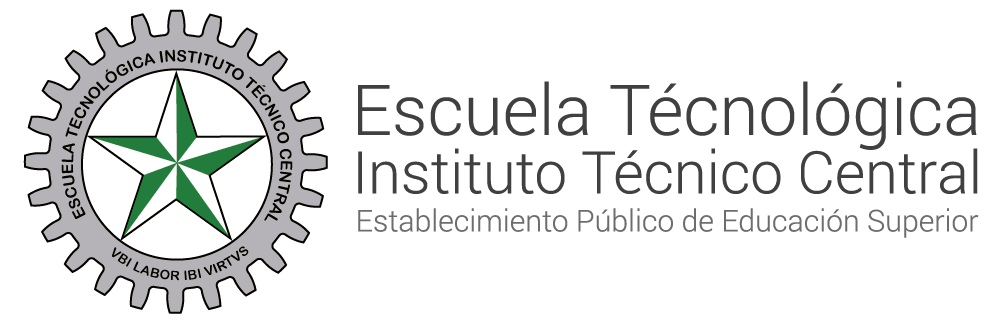

**SISTEMAS DE CONTROL II  **

# **Solución ecuaciones en diferencias**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

**CoAutores: Elberth Dirjhampher Ariza Ferreira, Jesús Manuel Pardo Gonzalez**

# Metodología

Para desarrollar los ejercicios relacionados con la transformada Z, se seguirá el siguiente enfoque metodológico:

Primero, se resolverá cada ejercicio de forma **manual**, es decir, aplicando los procedimientos matemáticos paso a paso, utilizando ecuaciones escritas y desarrollos teóricos.

Posteriormente, se implementará un **algoritmo **en MATLAB que permita verificar y validar los resultados obtenidos, así como entender el uso de las funciones propias del software para este tipo de análisis.

De esta manera, se busca no solo obtener la solución correcta, sino también comprender a fondo el procedimiento matemático y su aplicación computacional, fortaleciendo tanto la parte teórica como práctica.

Encuentre la transformada z inversas para y[k] de las siguientes funciones, aplique fracciones parciales y despues utilice la tabla de transformada Z

# Solución Aplicando Procedimientos Matematicos:

## Paso 1

Pirmero vamos a ablicar lo que son fraciones parciales a la ecuacion:


$$y\left(z\right)=\frac{10}{\left(z-1\right)\left(z-0\ldotp 5\right)}$$



$$y\left(z\right)=\frac{A}{\left(z-1\right)}+\frac{B}{\left(z-0\ldotp 5\right)}\;\;\to \;\;\;\frac{10}{\left(z-1\right)\left(z-0\ldotp 5\right)}=\frac{A}{\left(z-1\right)}+\frac{B}{\left(z-0\ldotp 5\right)}$$


Multiplicamos ambos lados por el denominador común (z-1)(z-0.5), y obtenemos:


$$10=A\;\left(z-0\ldotp 5\right)+B\left(z-1\right)\;\;\;\to \;\;10=\textrm{Az}-0\ldotp 5A+B\left(z-1\right)$$


Agrupamos términos que tengamos en común, en este caso es la z, y quedaria de la siguiente manera:


$$10=\left(A+B\right)z+\left(-0\ldotp 5A-B\right)$$


Igualamos lo que son los coeficientes:


$$A+B=0$$



$$-0\ldotp 5A-B=10$$


## Paso 2

Ya teniendo los coeficientes igualados podemos despejar cualquiera de las expresiones ya sea A o B:


$$A+B=0\;\;\;\to \;\;B=-A$$
   


$$-0\ldotp 5A-B=10\;\to \;-0\ldotp 5A-\left(-A\right)=10\;\to 0\ldotp 5A=10$$



$$A=\frac{10}{0\ldotp 5}\;\;\to A=20$$
     

## Paso 3

Ya con los valores de A que es 20, podemos hallar también B.


$$-0\ldotp 5A-B=10\;\;\;\to \;-0\ldotp 5\left(20\right)-B=10\;\;\to -10-B=10\;\;\;\;\;\;\to \;\;\;\;\;\;\;\;\;\;\;B=-20$$



$$Y\left(z\right)=\frac{20}{z-1}-\frac{20}{z-0\ldotp 5}$$


## Paso 4 

Aplicamos la tabla de la transformada z inversa, para eso vamos a buscar coincidentes en la siguiente imagen:

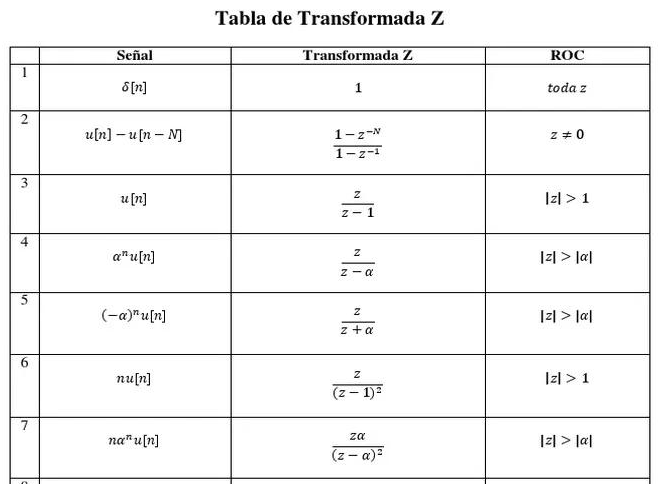

Si nos damos cuenta, la que mas se alinea a nuestro caso es la numero 4:


$$Z^{-1} \;\left\lbrace \frac{z}{z-a}\right\rbrace =a^n \bullet u\left\lbrack n\right\rbrack$$


Quedándonos de la siguiente manera:


$$\frac{20}{z-1}=20{\left(1\right)}^n \bullet u\left\lbrack n\right\rbrack \;\to \;20\bullet u\left\lbrack n\right\rbrack$$



$$\frac{20}{z-0\ldotp 5}=20{\left(0\ldotp 5\right)}^n \bullet u\left\lbrack n\right\rbrack \;\to \;20\bullet u\left\lbrack n\right\rbrack$$


## Paso 5 

Por ultimo unificamos y simplificamos si es posible.


$$y\;\left\lbrack k\right\rbrack =\;20\bullet u\left\lbrack n\right\rbrack \;-20{\left(0\ldotp 5\right)}^n \bullet u\left\lbrack n\right\rbrack$$


# Solución con Algoritmo Matlab

Una vez finalizado el procedimiento de forma manual o matemática, damos paso a la siguiente parte de nuestra metodología: la implementación del **algoritmo** en MATLAB, el cual nos permite verificar los resultados obtenidos manualmente y, además, entender cómo se pueden resolver este tipo de ejercicios por medio de esta herramienta.

En esta etapa, cada línea del código será explicada detalladamente:

b = [10];                
a = [1 -1.5 0.5];    

Aquí definimos el sistema de manera para que MATLAB lo entienda:

- El denominador se expandió:$\left(z-1\right)\left(z-0\ldotp 5\right)\;\to \;z^{2\;} -1\ldotp 5+0\ldotp 5$

- Entonces `a = [1 -1.5 0.5]` representa ese polinomio.

[r, p, k] = residuez(b, a);

Esta función descompone el sistema en **fracciones parciales**, devolviendo:

- `r`: los **residuos**, o sea los coeficientes de cada fracción parcial.

- `p`: los **polos**, que son los valores que generan cada término.

- `k`: si hubiera un término constante extra.

syms z
Y_z_fract = simplify(r(1)/(1 - p(1)*z^(-1))) + simplify(r(2)/(1 - p(2)*z^(-1)))

La idea es reconstruir la función Y(z) a partir de la expansión en fracciones parciales obtenida con `residuez`.

syms k
y_k = simplify(iztrans(Y_z_fract, z, k))

Se emplea para hallar la transformada inversa z

t = 0:10;                           % Valores de k 
y_t = 20 * (1 - (0.5).^t);          % Ecuación obtenida de y[k]

$$Y\_z\_fract = \frac{20\,z}{z-1}-\frac{20\,z}{2\,z-1}$$

$$y\_k = 20-10\,{\left(\frac{1}{2}\right)}^{k}$$

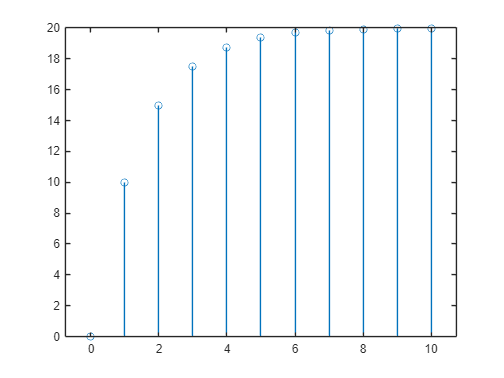

stem(t, y_t)             % Gráfica discreta